A.1

a = imread('lenaG.bmp')

a = 512×512 uint8 矩阵
   162   162   162   161   162   156   163   160   164   160   161   159   155   162   159   154   157   156   161   161   153   156   154   157   154   157   155   152   156   154   154   156   153   157   154   159   158   166   159   166   166   165   166   171   170   175   173   170   172   172
   162   162   162   161   162   156   163   160   164   160   161   159   155   162   159   154   157   156   161   161   153   156   154   157   154   157   155   152   156   154   154   156   153   157   154   159   158   166   159   166   166   165   166   171   170   175   173   170   172   172
   162   162   162   161   162   156   163   160   164   160   161   159   155   162   159   154   157   156   161   161   153   156   154   157   154   157   155   152   156   154   154   156   153   157   154   159   158   166   159   166   166   165   166   171   170   175   173   170   172   172
   162   162   162   161   162   156   163   160   164   160   161   159   1

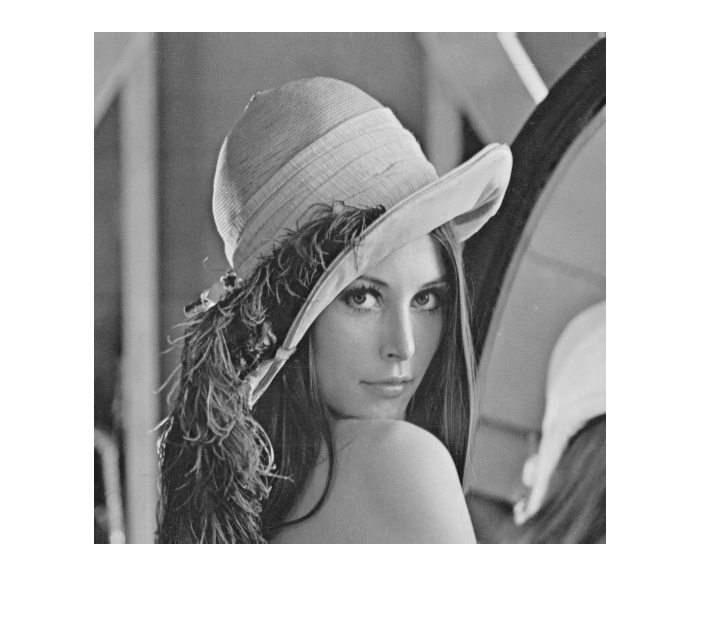

imshow(a)

A.2

imwrite(a,'test.jpg')

A.3

imwrite(a,'test.tiff')
imwrite(a,'test.jpeg')
imwrite(a,'test.gif')

A.4

b = imread('test.jpeg')

b = 512×512 uint8 矩阵
   160   162   163   161   158   157   159   162   164   162   158   156   159   162   159   151   155   159   162   160   155   152   154   157   156   155   155   154   154   155   155   156   153   154   156   159   161   162   163   163   167   167   167   169   172   173   173   171   174   169
   161   162   163   161   158   157   159   162   164   163   159   156   159   162   159   152   156   159   162   160   156   153   154   157   156   155   155   154   154   155   155   156   153   154   156   158   160   162   163   164   167   167   167   169   172   173   173   171   174   169
   162   163   163   161   159   159   160   162   164   163   160   157   159   162   159   153   157   160   162   160   157   154   155   157   155   155   154   154   154   154   155   155   153   154   156   158   160   162   163   164   167   167   167   169   172   173   173   171   173   170
   163   163   162   161   160   160   161   162   163   163   161   158   1

a - b 

ans = 512×512 uint8 矩阵
   2   0   0   0   4   0   4   0   0   0   3   3   0   0   0   3   2   0   0   1   0   4   0   0   0   2   0   0   2   0   0   0   0   3   0   0   0   4   0   3   0   0   0   2   0   2   0   0   0   3
   1   0   0   0   4   0   4   0   0   0   2   3   0   0   0   2   1   0   0   1   0   3   0   0   0   2   0   0   2   0   0   0   0   3   0   1   0   4   0   2   0   0   0   2   0   2   0   0   0   3
   0   0   0   0   3   0   3   0   0   0   1   2   0   0   0   1   0   0   0   1   0   2   0   0   0   2   1   0   2   0   0   1   0   3   0   1   0   4   0   2   0   0   0   2   0   2   0   0   0   2
   0   0   0   0   2   0   2   0   1   0   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   2   1   0   3   0   0   1   0   3   0   2   0   5   0   2   0   0   0   2   0   2   0   0   0   1
   0   0   1   1   2   0   3   0   3   0   0   2   0   3   1   1   0   0   2   3   0   1   0   2   0   3   2   0   3   1   0   1   0   3   0   3   0   6   0   2   0   0   0 

A.5

a = imread("lenaG.bmp");
a(1:10,1:10)

ans = 10×10 uint8 矩阵
   162   162   162   161   162   156   163   160   164   160
   162   162   162   161   162   156   163   160   164   160
   162   162   162   161   162   156   163   160   164   160
   162   162   162   161   162   156   163   160   164   160
   162   162   162   161   162   156   163   160   164   160
   164   164   157   155   161   159   158   159   159   160
   160   160   163   158   160   161   159   155   159   162
   158   158   155   156   158   158   156   157   158   160
   155   155   157   157   159   160   157   157   163   157
   155   155   157   158   154   154   155   157   161   153


A.6

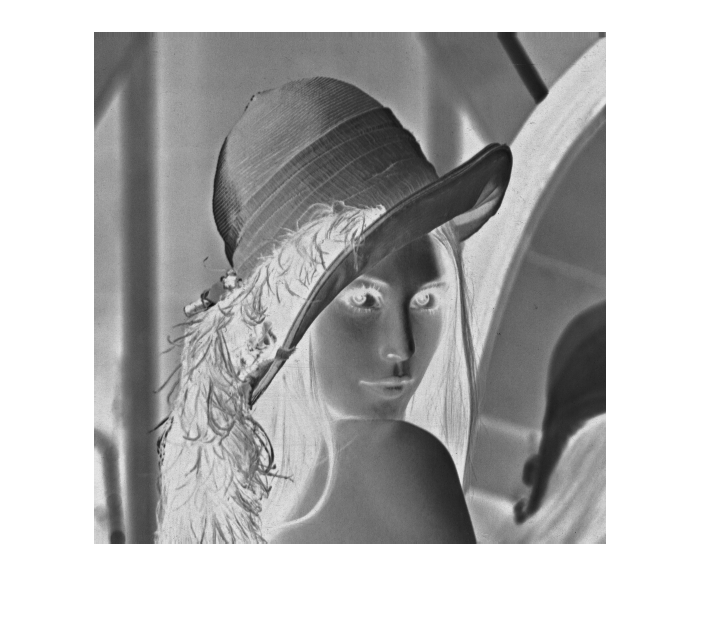

a = imread("lenaG.bmp");
imshow(255-a)

A.7

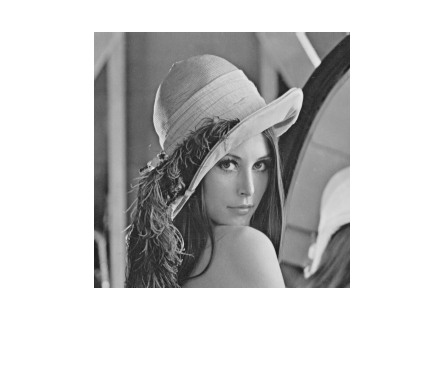

a = imread("lenaG.bmp");
clear("b")
[r,c] = size(a);
a = double(a); 
for i = 1: 2 : r
    for j = 1: 2 : c
        sum = a(i,j)+a(i+1,j)+a(i,j+1)+a(i+1,j+1);
        b((i+1)/2,(j+1)/2) = sum/4;
    end
end
a = uint8(b);
imshow(a)

size(a)

ans =    256   256


A.8

a = imread('lenaG.bmp');
[r,c] = size(a)

r = 512

c = 512

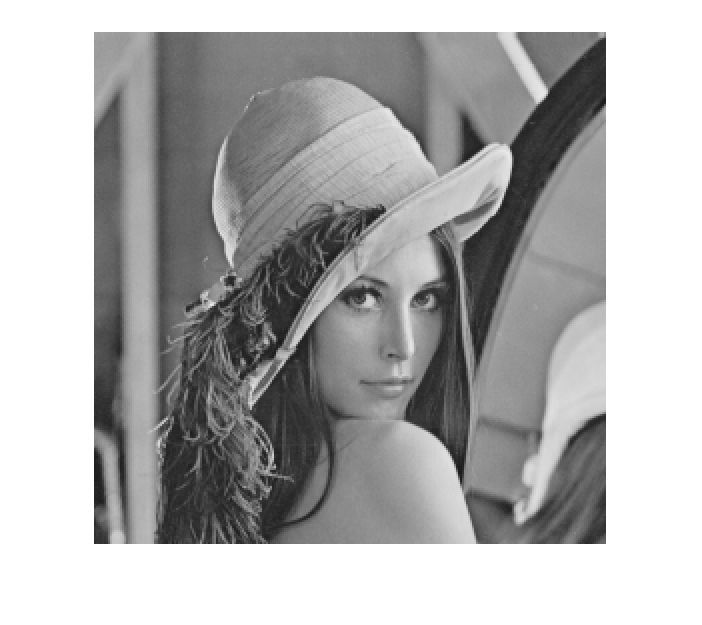

a = double(a);
for i = 1: 2 : r
    for j = 1: 2 : c
        sum = a(i,j)+a(i+1,j)+a(i,j+1)+a(i+1,j+1);
        a(i,j)      = sum/4;
        a(i+1,j)    = sum/4;
        a(i,j+1)    = sum/4;
        a(i+1,j+1)  = sum/4;
    end
end
a = uint8(a);
imshow(a)

a - imread("lenaG.bmp")

ans = 512×512 uint8 矩阵
   0   0   0   1   0   3   0   2   0   2   0   1   4   0   0   3   0   1   0   0   2   0   2   0   2   0   0   2   0   1   1   0   2   0   3   0   4   0   4   0   0   1   3   0   3   0   0   2   0   0
   0   0   0   1   0   3   0   2   0   2   0   1   4   0   0   3   0   1   0   0   2   0   2   0   2   0   0   2   0   1   1   0   2   0   3   0   4   0   4   0   0   1   3   0   3   0   0   2   0   0
   0   0   0   1   0   3   0   2   0   2   0   1   4   0   0   3   0   1   0   0   2   0   2   0   2   0   0   2   0   1   1   0   2   0   3   0   4   0   4   0   0   1   3   0   3   0   0   2   0   0
   0   0   0   1   0   3   0   2   0   2   0   1   4   0   0   3   0   1   0   0   2   0   2   0   2   0   0   2   0   1   1   0   2   0   3   0   4   0   4   0   0   1   3   0   3   0   0   2   0   0
   1   1   0   0   0   4   0   0   0   1   0   0   1   0   0   2   0   0   0   0   1   0   0   0   2   0   0   2   0   0   2   0   2   0   0   0   2   0   4   0   0   1   3 

A.9

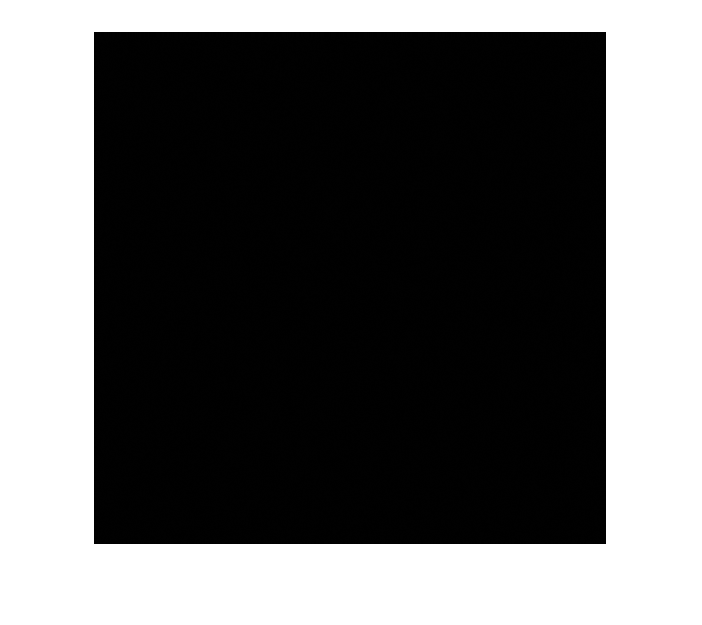

a = imread("lenaG.bmp");
imshow(bitand(a,bin2dec('00000001')))

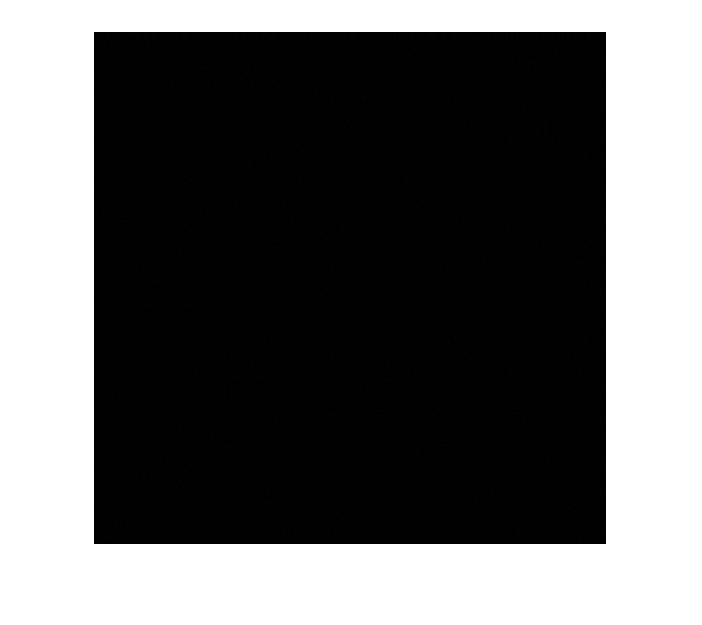

imshow(bitand(a,bin2dec('00000010')))

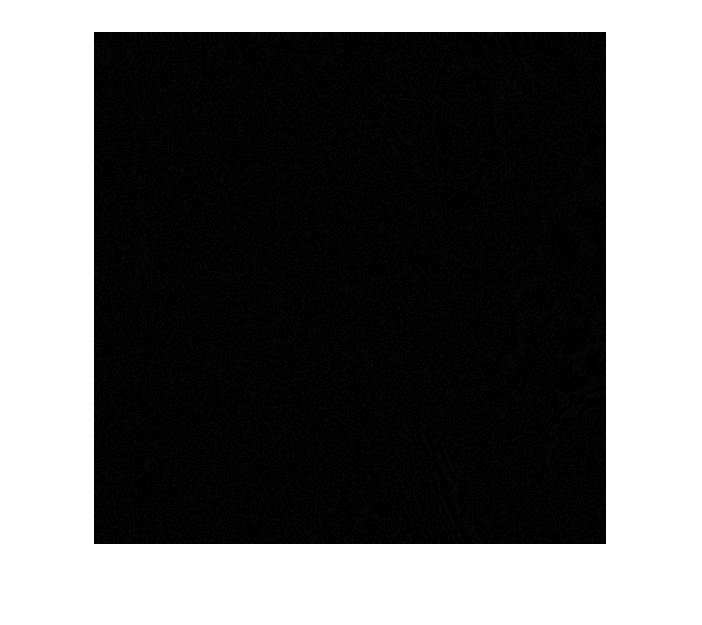

imshow(bitand(a,bin2dec('00000100')))

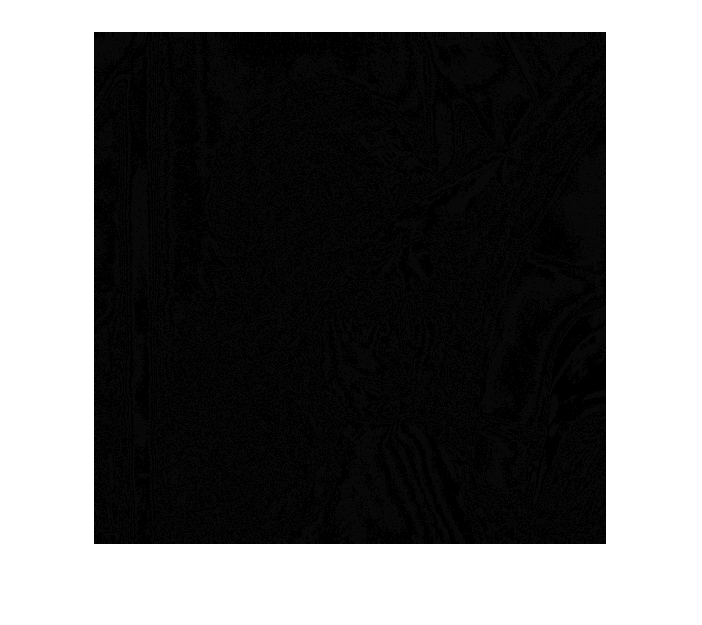

imshow(bitand(a,bin2dec('00001000')))

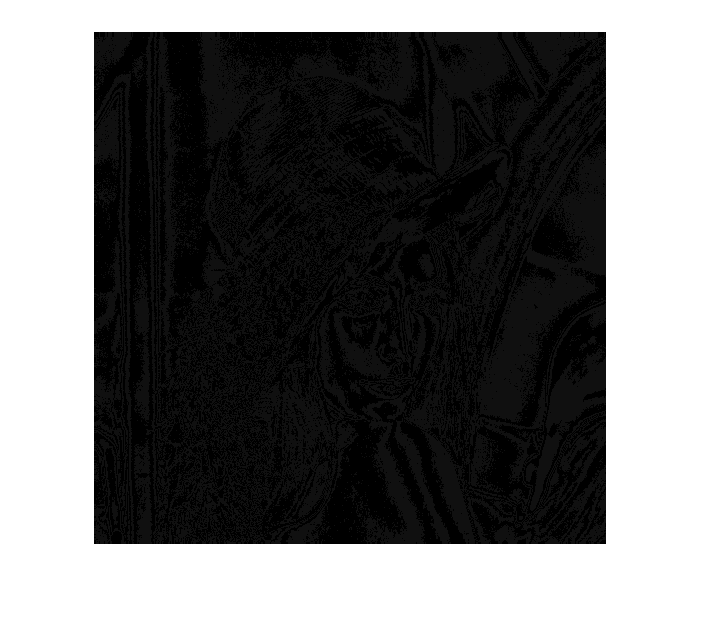

imshow(bitand(a,bin2dec('00010000')))

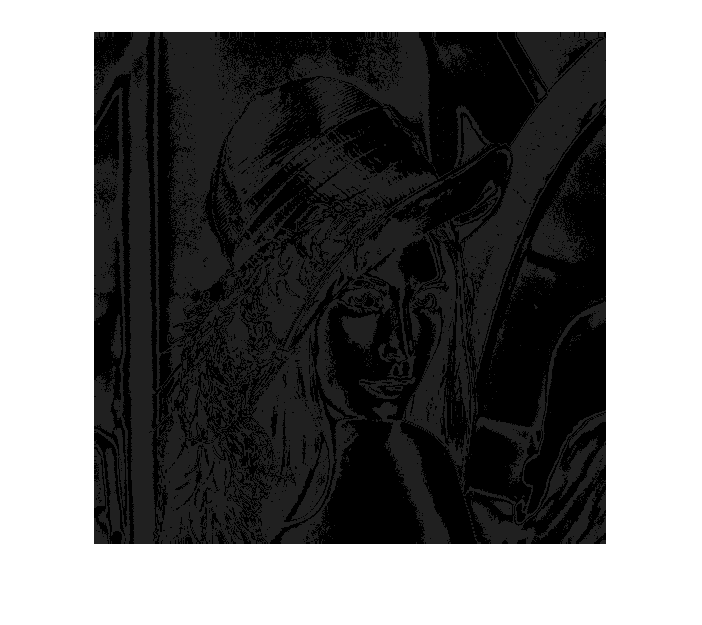

imshow(bitand(a,bin2dec('00100000')))

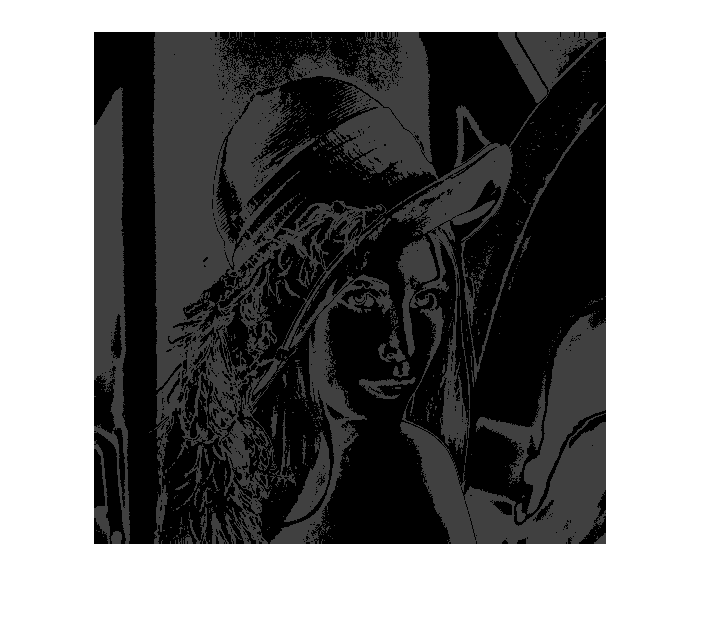

imshow(bitand(a,bin2dec('01000000')))

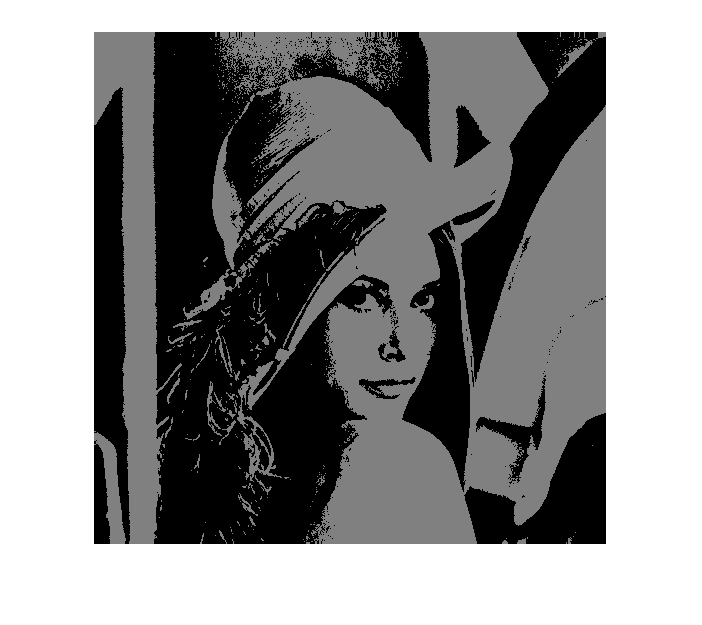

imshow(bitand(a,bin2dec('10000000')))